syms mu sekma x mui sekmai y theta u0 u1 u2 u3 H R beta muiu sekmaii;
mu = vpa(mu);
sekma = vpa(sekma);
x = vpa(x);


mui = vpa(mui);
sekmai = vpa(sekmai);

H = 20;
R = 3;
u0 = R*0.009 ; % 0.009是地层损失径向相对收敛系数
u2 = R*0.00452;      % 0.0045是椭圆化长轴相对收敛系数
u1 = R-R^2/(R+u2);
u3 = R*0.003;         % 0.0033是整体下沉相对位移系数
theta = 0.7854;           % 偏压角度，也是局部坐标角度
beta = 0.61;        %  地层主要影响角

muii = H + u3*cos(theta)+mui*cos(theta)+sekmai*sin(theta);
sekmaii = mui*sin(theta)-sekmai*cos(theta);

a = tan(beta)/mu;       % 0.94是2*tan(beta)
b = (tan(beta))^2*pi/mu^2;  % 0.884=(tan(beta)))^2
c = (x-sekma)^2;
d = sqrt(R^2-(H-mu)^2);    % 9=R^2   18=埋深
e = -d;

ai = tan(beta)/muii;
bi = (tan(beta))^2*pi/muii^2;
ci = (x+u3*sin(theta)+sekmaii)^2;
di = (R-u0+u2)*sqrt(1-(mui/(R-u0-u1))^2);  % 9=（R1）^2   18.02=埋深，由损失率计算得到
ei = -di;

al = H-R;
bl = H+R;

ali = u0 + u1 - R;
bli = R -u0 -u1;

FZ = a*exp(-b*c);
FZi = ai*exp(-bi*ci);

% 利用Legendre-Gauss求积法对FZ进行积分
n = 20; % 积分阶数
[xi, wi] = lgwt(n, e, d); % Legendre-Gauss求积节点和权重
GZH = 0;
for i = 1:n
    GZH = GZH + wi(i)*subs(FZ, sekma, xi(i));
end
ni = 20; % 积分阶数
[xii, wii] = lgwt(ni, ei, di); % Legendre-Gauss求积节点和权重
GZHi = 0;
for j = 1:ni
    GZHi = GZHi + wii(j)*subs(FZi, sekmai, xii(j));
end

% 利用Legendre-Gauss求积法对GZH进行积分
n = 20; % 积分阶数
[xi, wi] = lgwt(n, al, bl); % Legendre-Gauss求积节点和权重，21=R+H,15=H-R
MH = 0;
for i = 1:n
    MH = MH + wi(i)*subs(GZH, mu, xi(i));
end

n = 20; % 积分阶数
[xii, wii] = lgwt(n, ali, bli); % Legendre-Gauss求积节点和权重
MHi = 0;
for j = 1:n
    MHi = MHi + wii(j)*subs(GZHi, mui, xii(j));
end

% 利用插值的方式画出MH和x的图像
MHX = MH-MHi

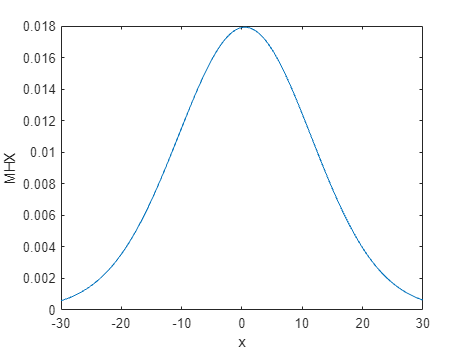


x_range = linspace(-3, 3, 1000);
MHX_values = zeros(size(x_range));
for i = 1:length(x_range)
    MHX_values(i) = double(subs(MHX, x, x_range(i)));
end
plot(x_range, MHX_values);
xlabel('x');
ylabel('MHX');

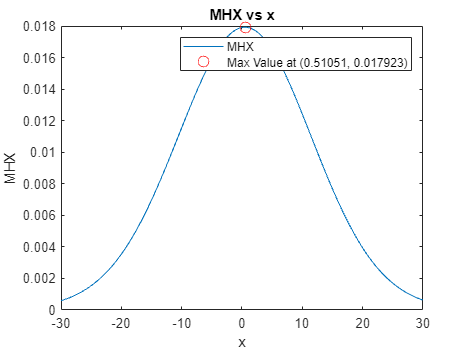


% Assume you have calculated MHX_values

% Find the maximum value of MHX_values and its index
[max_value, max_index] = max(MHX_values);

% Get the corresponding x value for the maximum point
x_max = x_range(max_index);
y_max = max_value;

% Plot MHX_values
plot(x_range, MHX_values);
hold on;

% Plot the maximum point with a red circle marker
plot(x_max, y_max, 'ro', 'MarkerSize', 8);

xlabel('x');
ylabel('MHX');
title('MHX vs x');

% Add a legend for the maximum point
legend('MHX', ['Max Value at (', num2str(x_max), ', ', num2str(y_max), ')']);

hold off;